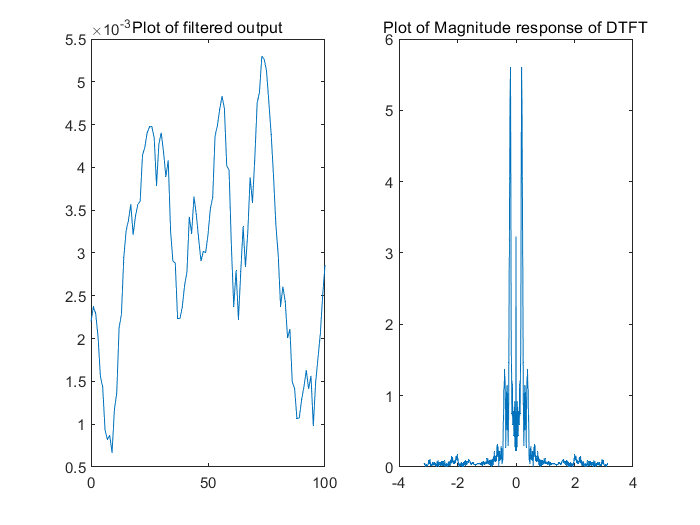

load nspeech1;
y0 = FIRfilter(nspeech1);
y1 = nspeech1(100:200);
y2 = nspeech1(100:1100);
y3 = y0(100:200);
y4 = y0(100:1100);
[X2,w2] = DTFT(y2,0);
[Xmax,Imax] = max(abs(X2));
[X4,w4] = DTFT(y4,0);
%plot([0:length(y1)-1],y1);title('Plot of the time domain of 101 samples');
%plot(w2,abs(X2));title('Plot of magnitude of DTFT for 1001 samples');
subplot(121);plot([0:length(y1)-1],y3);title('Plot of filtered output');
subplot(122);plot(w4,abs(X4));title('Plot of Magnitude response of DTFT');